# Build a robot step by step

clc;clear;
%Create a rigid body object.
body1 = rigidBody('body1')

body1 =   rigidBody with properties:

            Name: 'body1'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}
      Collisions: {}


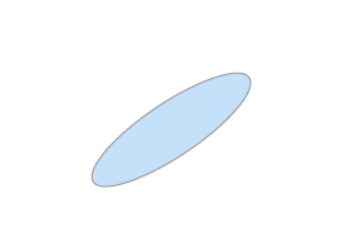

%Create a joint and assign it to the rigid body. 
jnt1 = rigidBodyJoint('jnt1','revolute');
% Define the home position property of the joint, HomePosition.
jnt1.HomePosition = pi/4;

% Set the joint-to-parent transform using a homogeneous transformation, tform.
% Use the trvec2tform function to convert from a translation vector to a homogenous
% transformation.ChildToJointTransform is set to an identity matrix.
tform = trvec2tform([0.25, 0.25, 0]); % User defined
setFixedTransform(jnt1,tform);
body1.Joint = jnt1;

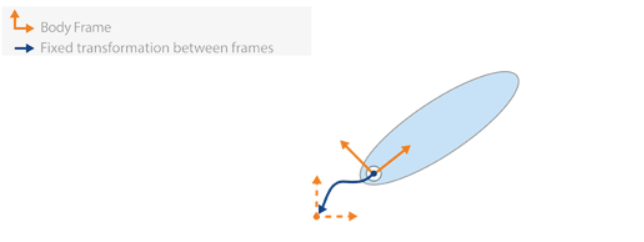

%Create a rigid body tree. This tree is initialized with a base coordinate frame to attach bodies to.
robot = rigidBodyTree;

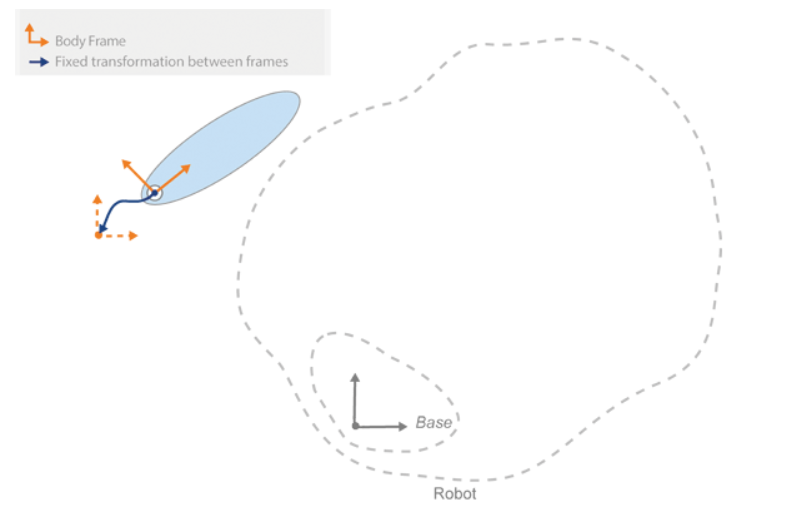

%Add the first body to the tree. Specify that you are attaching it to the base of the tree.
% The fixed transform defined previously is from the base (parent) to the first body.
addBody(robot,body1,'base')

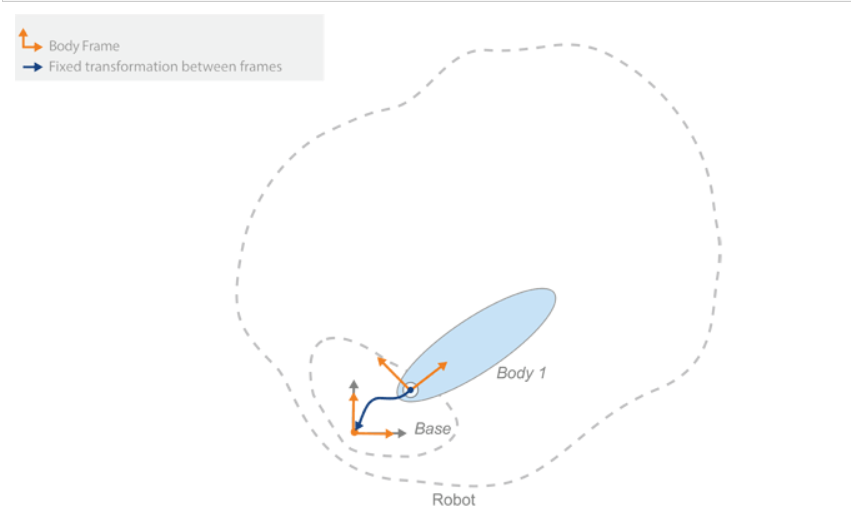

%Create a second body. Define properties of this body and attach it to the first rigid body. 
% Define the transformation relative to the previous body frame.
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
jnt2.HomePosition = pi/6; % User defined
tform2 = trvec2tform([1, 0, 0]); % User defined
setFixedTransform(jnt2,tform2);
body2.Joint = jnt2;
addBody(robot,body2,'body1'); % Add body2 to body1

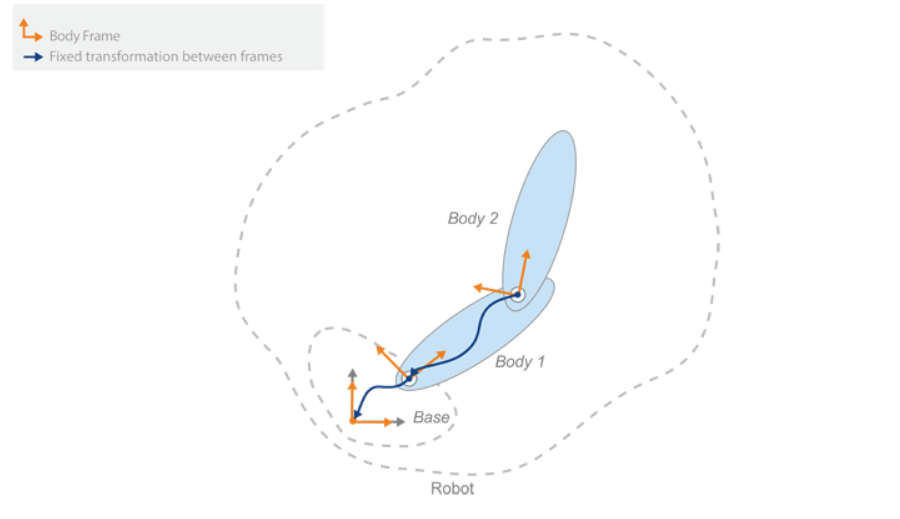

body3 = rigidBody('body3');
body4 = rigidBody('body4');
jnt3 = rigidBodyJoint('jnt3','revolute');
jnt4 = rigidBodyJoint('jnt4','revolute');
tform3 = trvec2tform([0.6, -0.1, 0])*eul2tform([-pi/2, 0, 0]); % User defined
tform4 = trvec2tform([1, 0, 0]); % User defined
setFixedTransform(jnt3,tform3);
setFixedTransform(jnt4,tform4);
jnt3.HomePosition = pi/4; % User defined
body3.Joint = jnt3

body3 =   rigidBody with properties:

            Name: 'body3'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}
      Collisions: {}


body4.Joint = jnt4

body4 =   rigidBody with properties:

            Name: 'body4'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}
      Collisions: {}


addBody(robot,body3,'body2'); % Add body3 to body2
addBody(robot,body4,'body2'); % Add body4 to body2

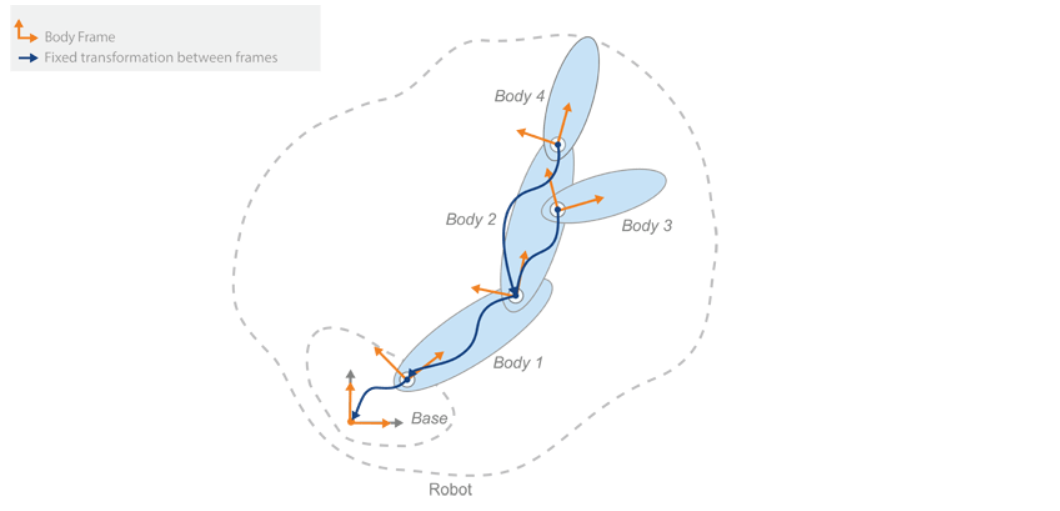

%If you have a specific end effector that you care about for control, define it as a rigid body with a fixed joint.
% For this robot, add an end effector to body4 so that you can get transformations for it.

bodyEndEffector = rigidBody('endeffector');
tform5 = trvec2tform([0.5, 0, 0]); % User defined
setFixedTransform(bodyEndEffector.Joint,tform5);
addBody(robot,bodyEndEffector,'body4');


%Now that you have created your robot, you can generate robot configurations. With a given configuration, you can also get a transformation between two body frames using getTransform. Get a transformation from the end effector to the base.

config = randomConfiguration(robot)

config = 1×4 struct array with fields:
    JointName
    JointPosition


tform = getTransform(robot,config,'endeffector','base')

tform =    -0.7538   -0.6571         0    0.0164
    0.6571   -0.7538         0    2.5638
         0         0    1.0000         0
         0         0         0    1.0000


%You can create a subtree from your existing robot or other robot models by using subtree. 
% Specify the body name to use as the base for the new subtree. You can modify this subtree by adding,
% changing, or removing bodies.

newArm = subtree(robot,'body2');
removeBody(newArm,'body3');
removeBody(newArm,'endeffector')

ans =   rigidBodyTree with properties:

     NumBodies: 1
        Bodies: {[1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'endeffector'}
      BaseName: 'body4'
       Gravity: [0 0 0]
    DataFormat: 'struct'


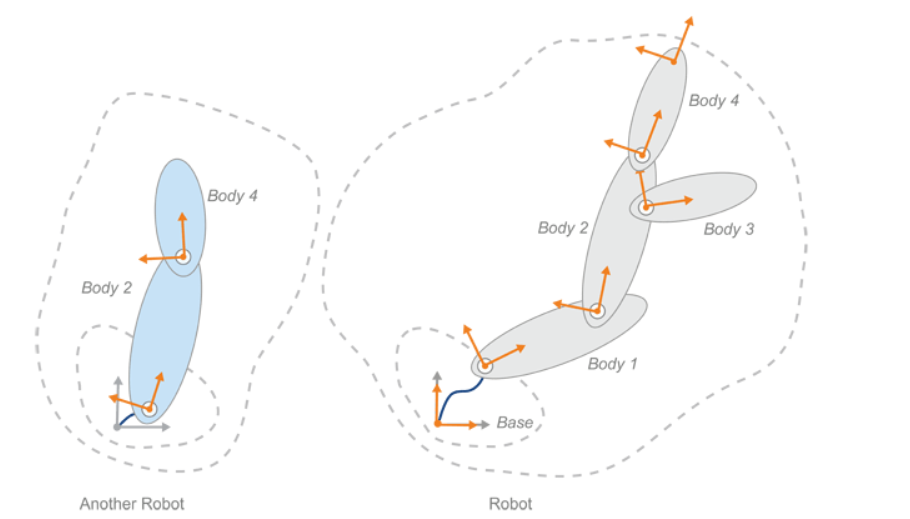

%You can also add these subtrees to the robot. Adding a subtree is similar to adding a body.
% The specified body name acts as a base for attachment, and all transformations on the subtree are relative
% to that body frame. Before you add the subtree, you must ensure all the names of bodies and joints are unique.
% Create copies of the bodies and joints, rename them, and replace them on the subtree. Call addSubtree to attach
% the subtree to a specified body.

newBody1 = copy(getBody(newArm,'body2'));
newBody2 = copy(getBody(newArm,'body4'));
newBody1.Name = 'newBody1';
newBody2.Name = 'newBody2';
newBody1.Joint = rigidBodyJoint('newJnt1','revolute');
newBody2.Joint = rigidBodyJoint('newJnt2','revolute');
tformTree = trvec2tform([0.2, 0, 0]); % User defined
setFixedTransform(newBody1.Joint,tformTree);
replaceBody(newArm,'body2',newBody1);
replaceBody(newArm,'body4',newBody2);

addSubtree(robot,'body1',newArm);

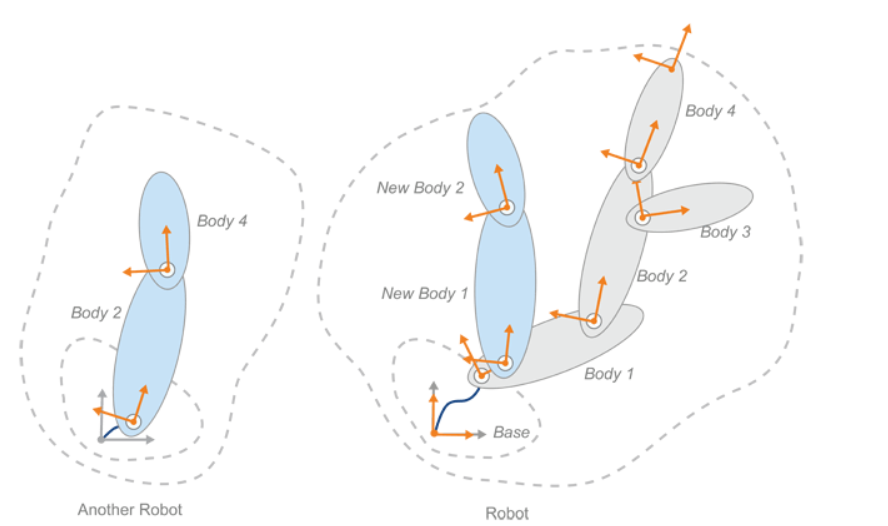

%Finally, you can use showdetails to look at the robot you built. Verify that the joint types are correct.

showdetails(robot)

--------------------
Robot: (7 bodies)

 Idx          Body Name             Joint Name             Joint Type          Parent Name(Idx)   Children Name(s)
 ---          ---------             ----------             ----------          ----------------   ----------------
   1              body1                   jnt1               revolute                   base(0)   body2(2)  newBody1(6)  
   2              body2                   jnt2               revolute                  body1(1)   body3(3)  body4(4)  
   3              body3                   jnt3               revolute                  body2(2)   
   4              body4                   jnt4               revolute                  body2(2)   endeffector(5)  
   5        endeffector        endeffector_jnt                  fixed                  body4(4)   
   6           newBody1                newJnt1               revolute                  body1(1)   newBody2(7)  
   7           newBody2                newJnt2               rev